# Lab 4

## Experiment 1

### Step 1

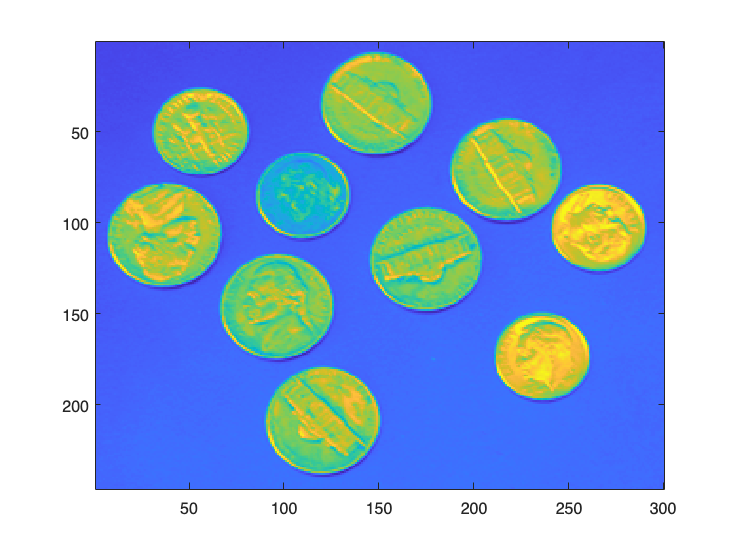

x1 = imread('coins.png');
figure(1)
imagesc(x1)

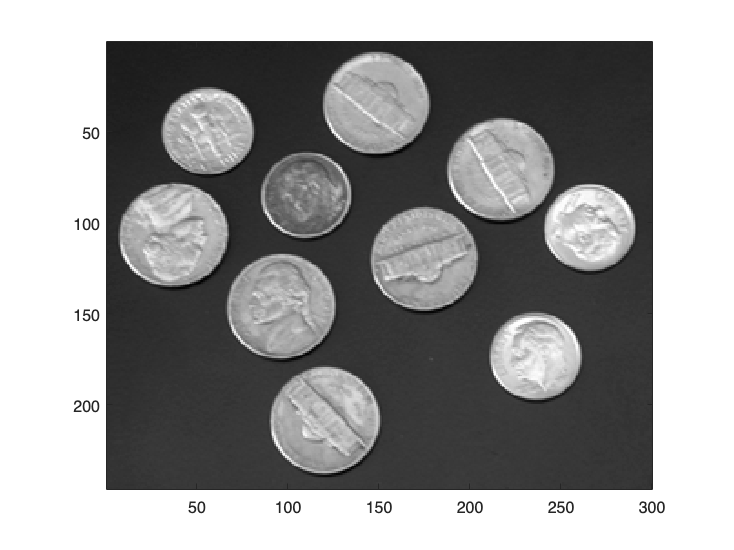

% Now try grayscale
figure(2)
imagesc(x1)
colormap('gray')
axis image

Without specifying grayscale, the image is blue and yellow. Grayscale looks like normal coins. 

### Step 2

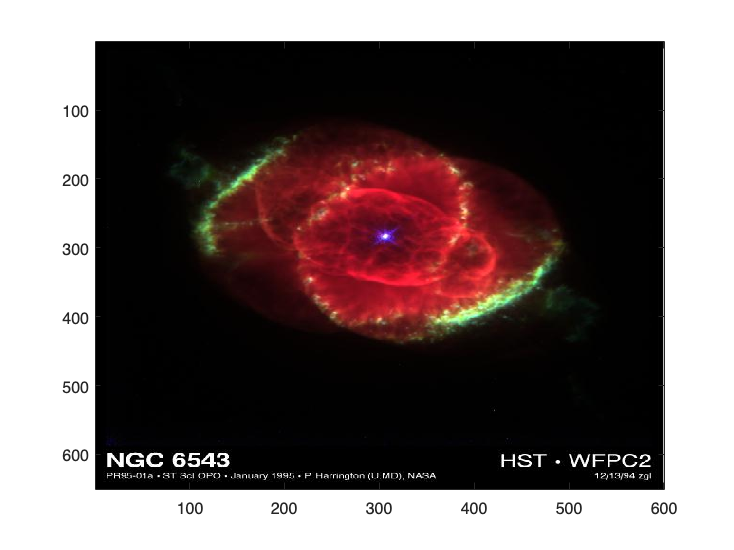

x2 = imread('ngc6543a.jpg');
imagesc(x2)

size(x2)

ans =    650   600     3


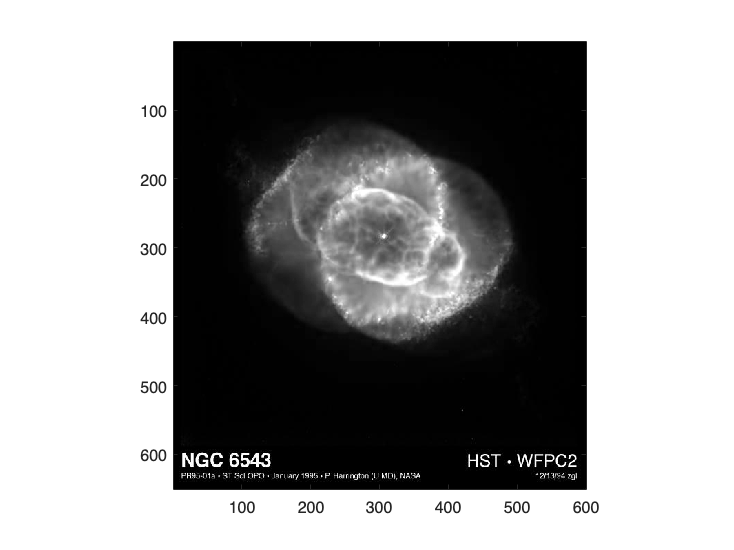

% First color plane
figure()
imagesc(x2(:,:,1))
colormap('gray')
axis image

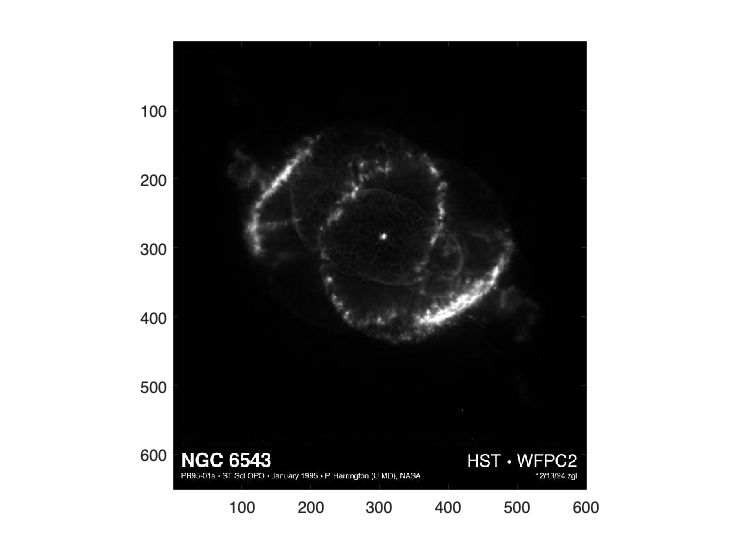

% Second color plane
figure()
imagesc(x2(:,:,2))
colormap('gray')
axis image

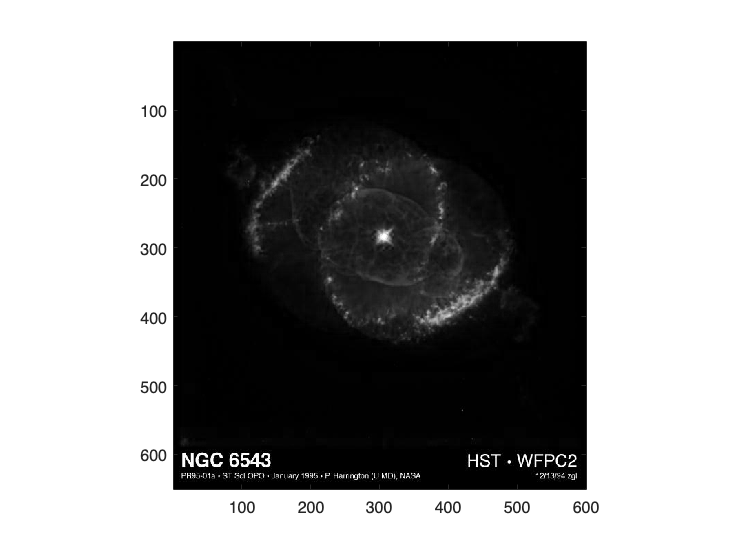

% Third color plane
figure()
imagesc(x2(:,:,3))
colormap('gray')
axis image

Based on these three images and the original, it seems that the planes correspond to RGB, in that order. The first grayscale image has a lot of activity throughout the red supernova, the second one is bright primarily on the green edges of the supernova, and the third one is bright at the blue center of the supernova.

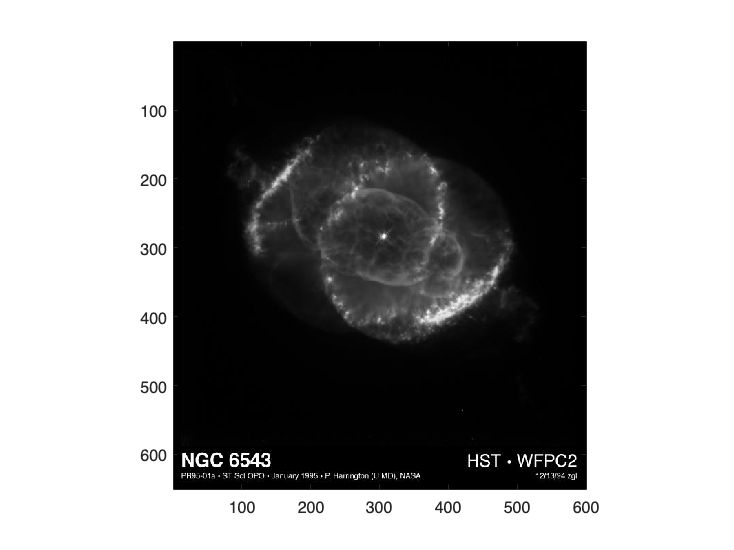

graySprNova = rgb2gray(x2);
imagesc(graySprNova)
colormap('gray')
axis image

### Step 3

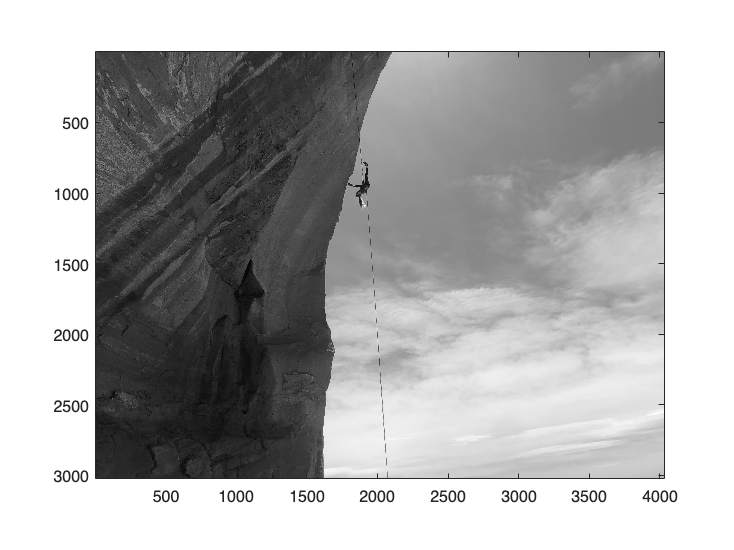

x3 = rgb2gray(imread("climbing.jpg"));
imagesc(x3)
colormap('gray')
axis image

## Experiment 2

### Step 1

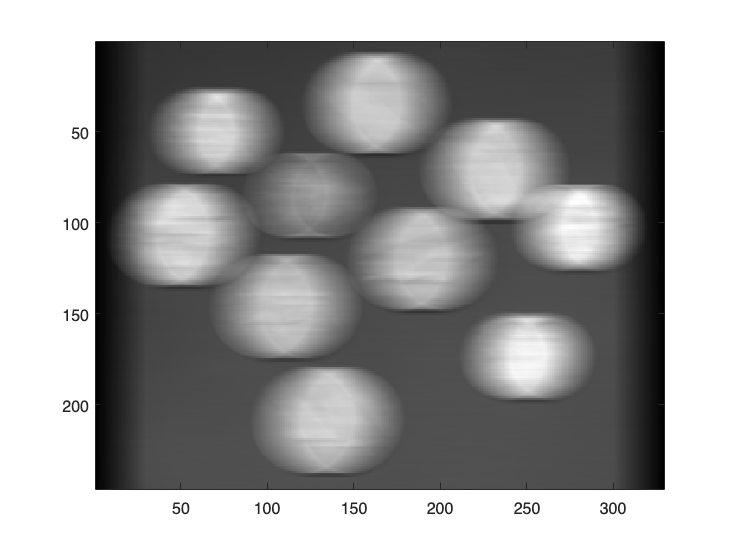

M = 30; % Should vary 10 to 30
h = (1/M) * rectwin(M);
h_hor = h.';

blurred_x1 = conv2(x1, h_hor);
imagesc(blurred_x1)

### Step 2

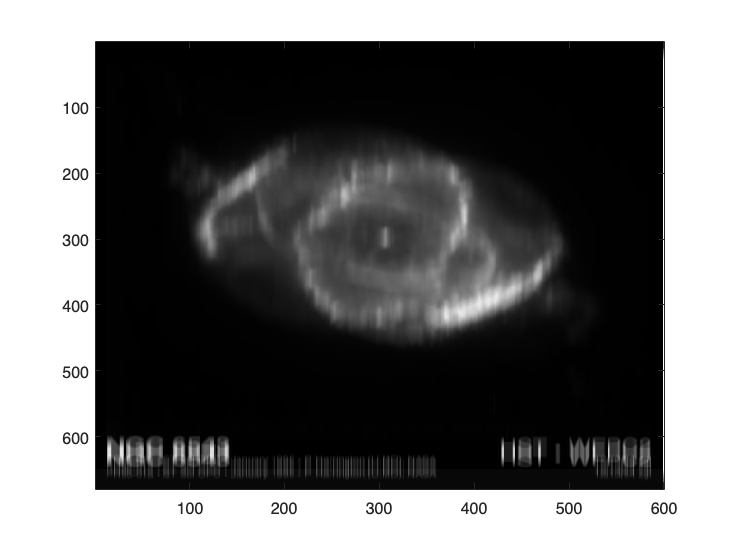

M = 30; % Should vary 10 to 30
h = (1/M) * rectwin(M);

blurred_x2 = conv2(graySprNova, h);
imagesc(blurred_x2)

### Step 4

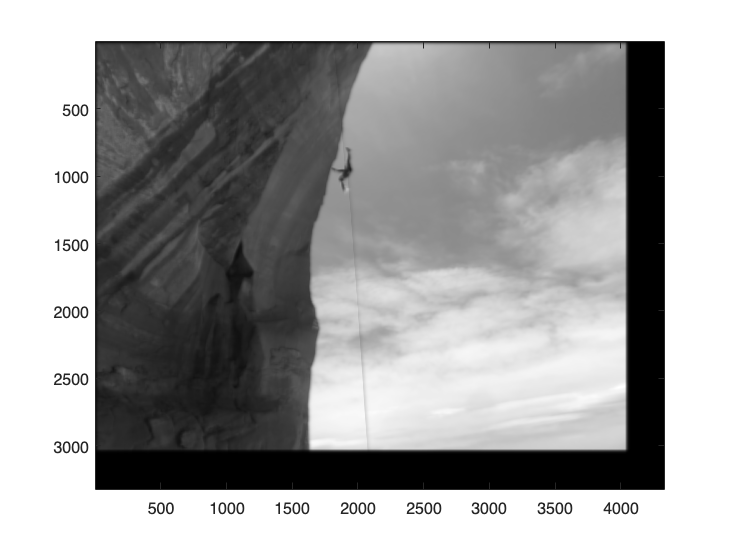

sigma = 15;
h_square = zeros(20*sigma);

for m = 1:20*sigma
    for n = 1:20*sigma
        h_square(m,n) = (1/(2*pi*sigma^2)) * exp(-(m^2 + n^2)/(2*sigma^2));
    end
end

blurred_x3 = conv2(x3, h_square);
imagesc(blurred_x3)

### Step 5

The image is centered in the top left of the frame. This is because images have their origin at the center, but ....

### Step 6

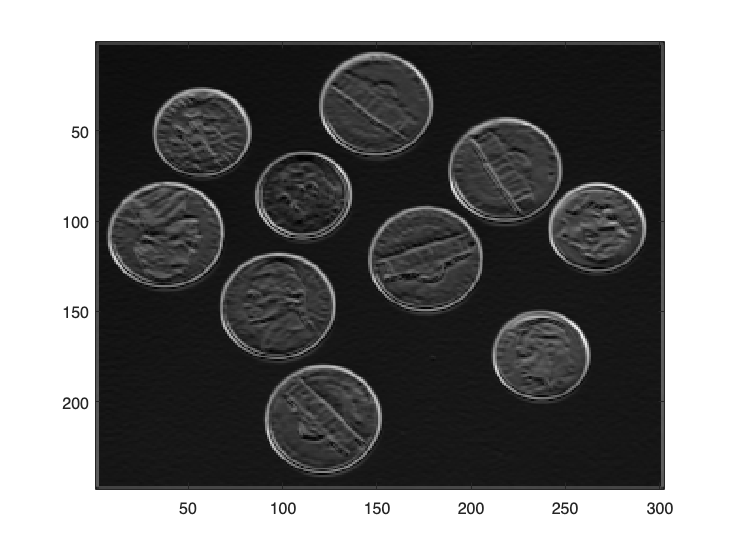

h1 = [-1 0 1; -2 0 2; -1 0 1];
h2 = [-1 -2 -1; 0 0 0; 1 1 1];

g = sqrt(conv2(h1, x1).^2 + conv2(h2,x1).^2);

imagesc(g)

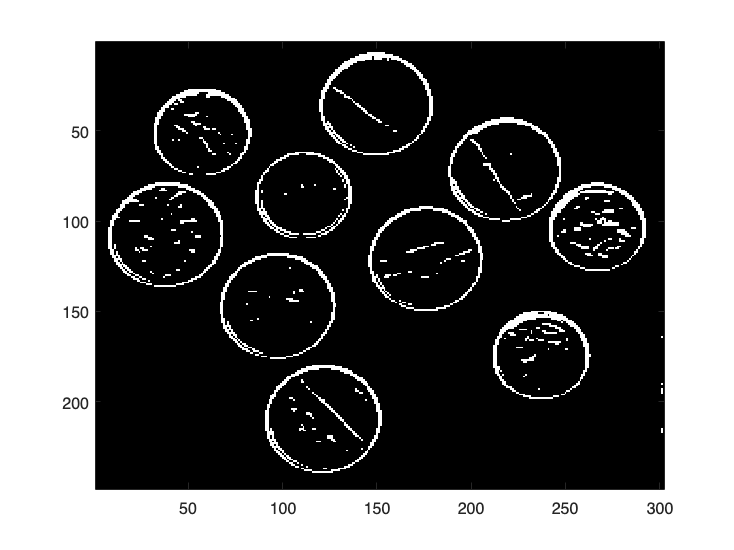

threshold = 300;

edges = (g > threshold);
imagesc(edges)

## Experiment 3

### Step 1

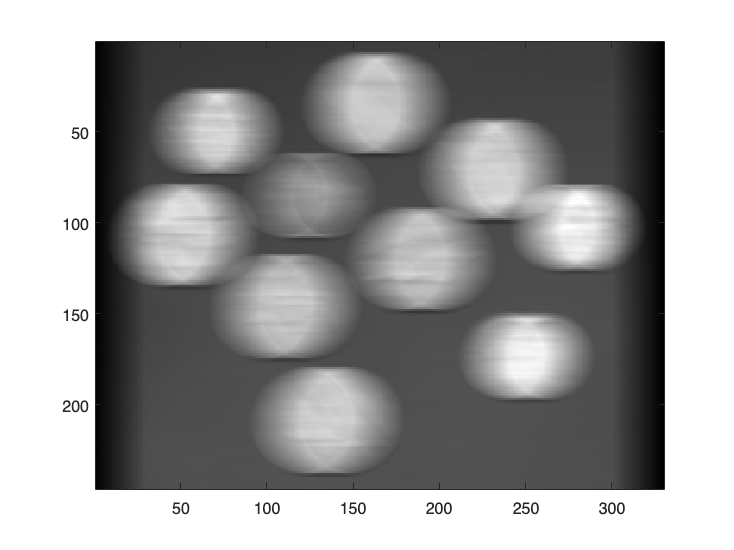

M = 30; % Should vary 10 to 30
h = (1/M) * rectwin(M);
h_hor = h.';

dims = size(x1);

blurred_x1 = ifft2(fft2(x1, dims(1), dims(2) + M).*fft2(h_hor, dims(1), dims(2) + M));
imagesc(blurred_x1)
colormap("gray")

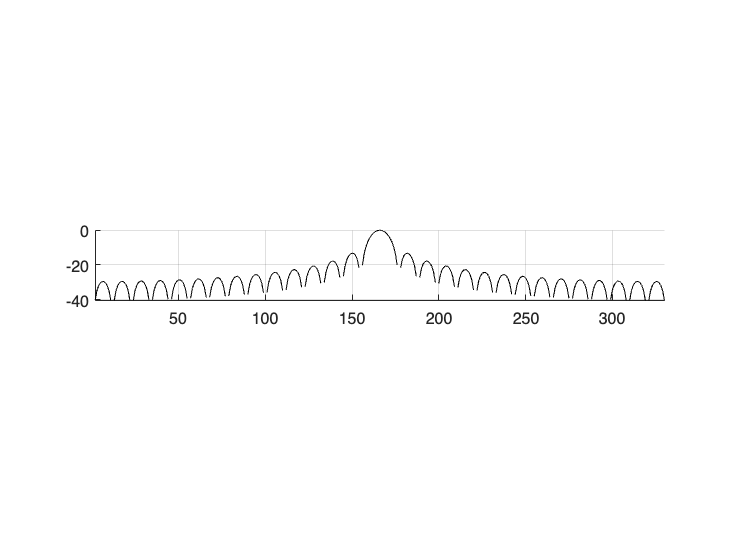


figure()
surf(20*log10(abs(fftshift(fft2(h_hor, dims(1), dims(2) + M)))))
view(0,0)
axis("image")

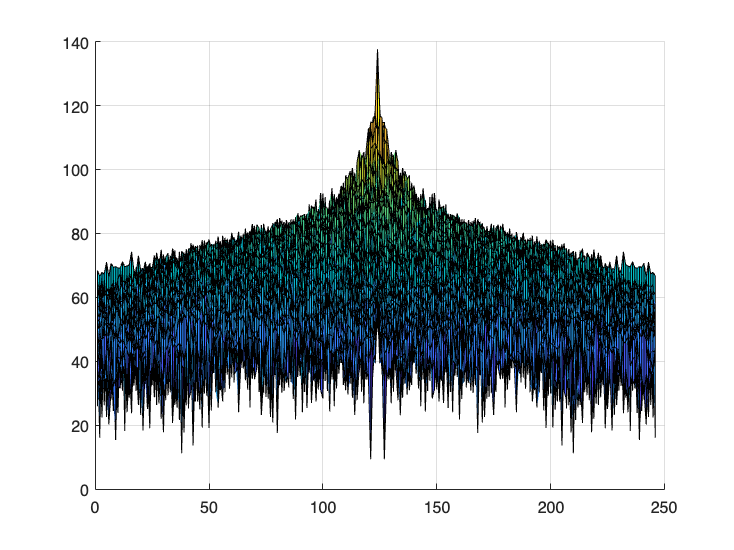


figure()
surf(20*log10(abs(fftshift(fft2(x1)))))
view(90,0)

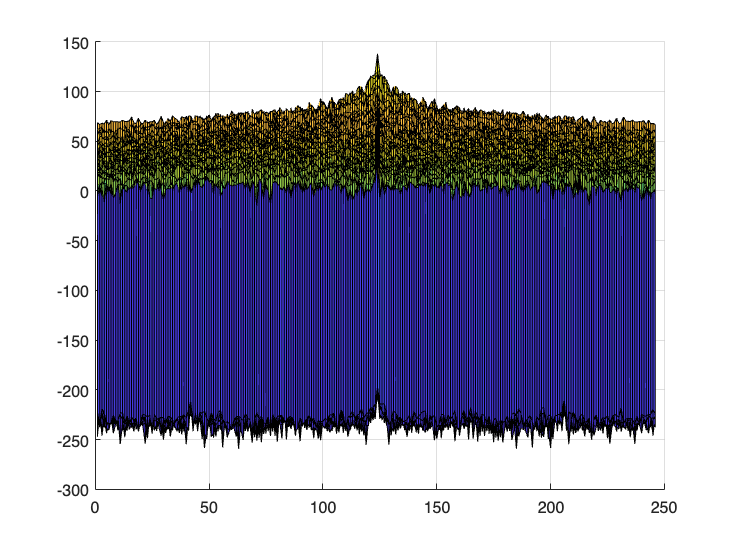


figure()
surf(20*log10(abs(fftshift(fft2(blurred_x1)))))
view(90,0)

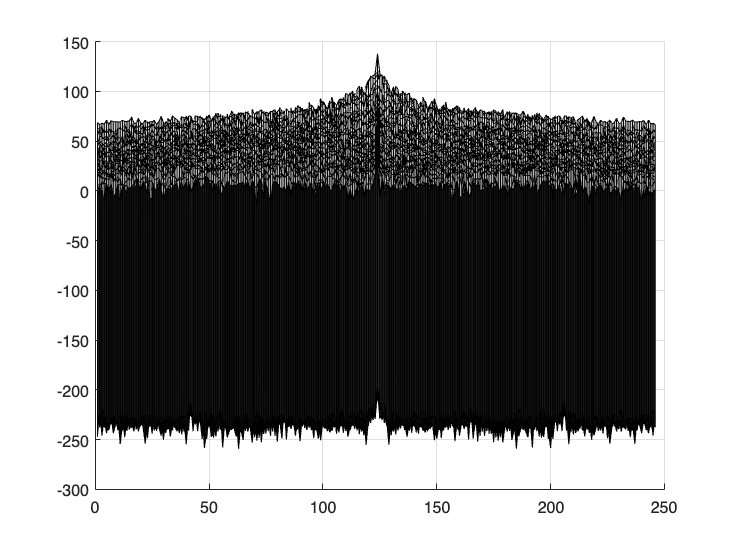

M = 30; % Should vary 10 to 30
h = (1/M) * rectwin(M);

dims = size(graySprNova);
colormap("gray")

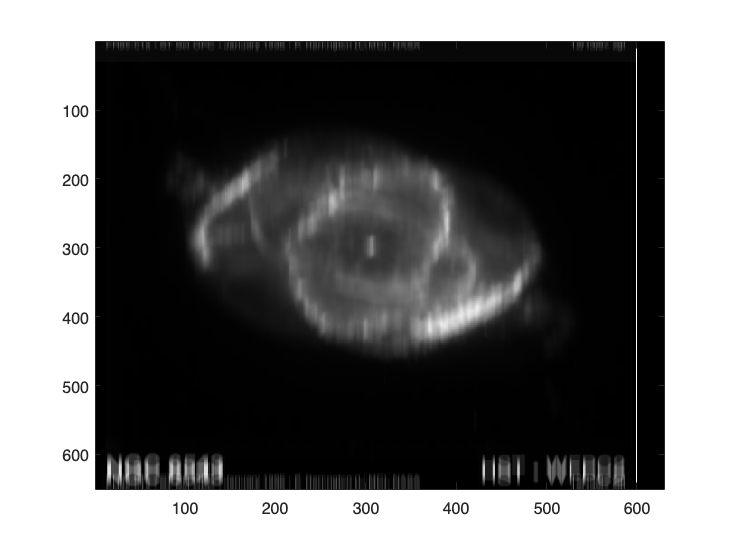


blurred_x2 = ifft2(fft2(graySprNova, dims(1), dims(2) + M) .* fft2(h, dims(1), dims(2) + M));
imagesc(blurred_x2)

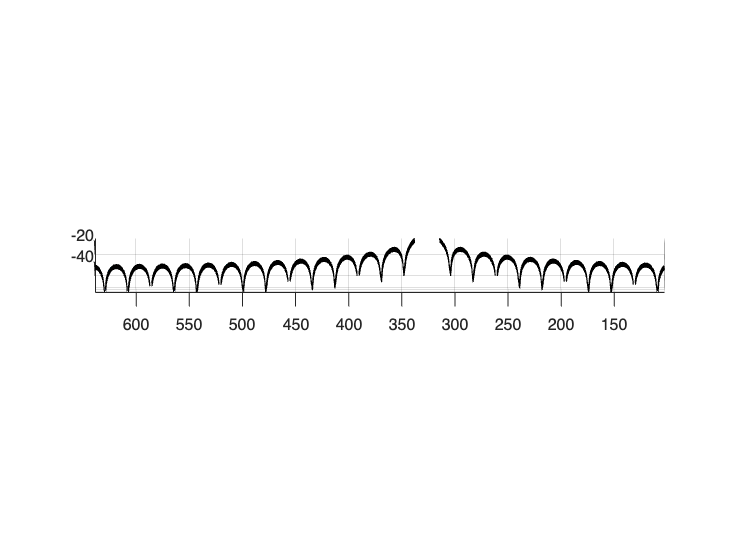


figure()
surf(20*log10(abs(fftshift(fft2(h, dims(1), dims(2) + M)))))
view(90,0)
axis("image")

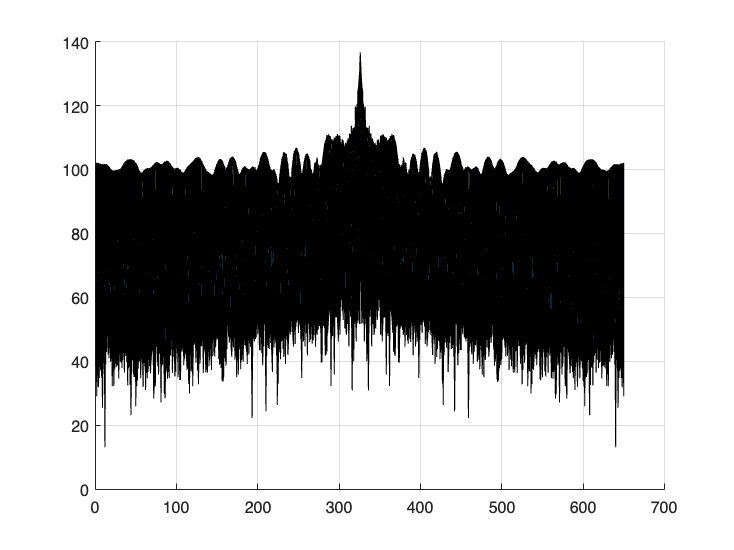


figure()
surf(20*log10(abs(fftshift(fft2(graySprNova)))))
view(90,0)

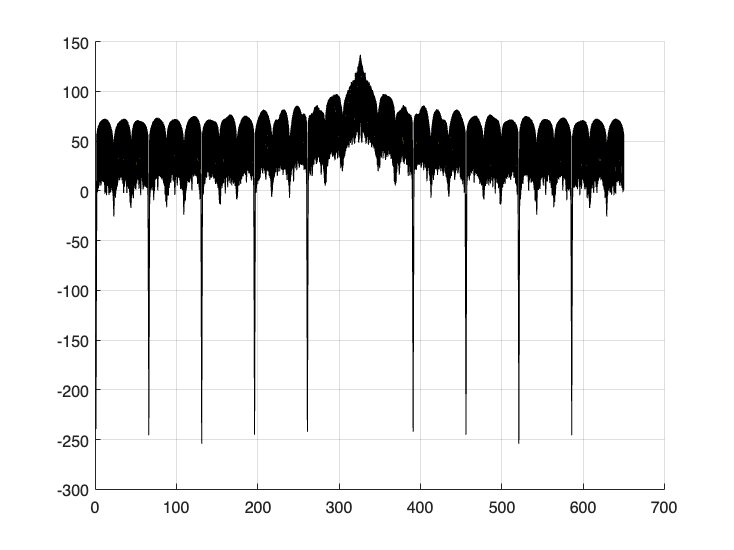


figure()
surf(20*log10(abs(fftshift(fft2(blurred_x2)))))
view(90,0)

sigma = 15;
h_square = zeros(20*sigma);

for m = 1:20*sigma
    for n = 1:20*sigma
        h_square(m,n) = (1/(2*pi*sigma^2)) * exp(-(m^2 + n^2)/(2*sigma^2));
    end
end

dims = size(x3);

blurred_x3 = ifft2(fft2(x3, dims(1), dims(2) + M) .* fft2(h_square, dims(1), dims(2) + M));
imagesc(blurred_x3)


figure()
surf(20*log10(abs(fftshift(fft2(h_square, dims(1), dims(2) + M)))))
% view(90,0)
axis("image")

figure()
surf(20*log10(abs(fftshift(fft2(x3)))))
view(90,0)

figure()
surf(20*log10(abs(fftshift(fft2(blurred_x3)))))
view(90,0)

### Step 4

% figure()
% surf(20*log10(abs(fftshift(fft2(x1)))))
% view(90,0)